% Parse the data from the specs
structure = SpecParser("global_specs.txt")

structure = struct with fields:
               task_type: 'wav'
            wav_filename: 'inputsignal.wav'
                  wav_fs: 10000
             signal_type: 'tone'
                      fs: 20000
       signal_duration_s: 4
           periodicity_s: 0.5000
             frequencies: [100 200 300 400]
     spectral_resolution: 1
             window_type: 'rect'
            stft_overlap: 50
               filtering: 'fir'
            filter_order: 4
    approximation_method: 'bp'
       cut_off_frequency: [1000 4000]
              x_lim_time: 0.0100
         y_lim_amplitude: 1
             x_axis_type: 'lin'
             y_axis_type: 'log'
         x_lim_frequency: 'nyquist'
                y_lim_au: 20


%Read .wav file
dir_name = ['C:',filesep,'Users',filesep,'dovyd',filesep,'OneDrive',filesep,'Desktop',filesep,'DSP',filesep,'Assignment',filesep] %Directory where the file is

dir_name = 'C:\Users\dovyd\OneDrive\Desktop\DSP\Assignment\'

f_name = structure.wav_filename; % File name
[y, fs_o] = audioread(fullfile(dir_name, f_name));% Read the audio file

% Resample with correct frequency
fs_y = structure.wav_fs; % Required sampling frequency
if (fs_o~=fs_y) % if original fs is not equal to required fs
    y = resample(y, fs_y, fs_o); % Resample from fs_o to fs_y
end
t_y = 0:1/fs_y:length(y)/fs_y-1/fs_y % Time vector for y

t_y =          0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049


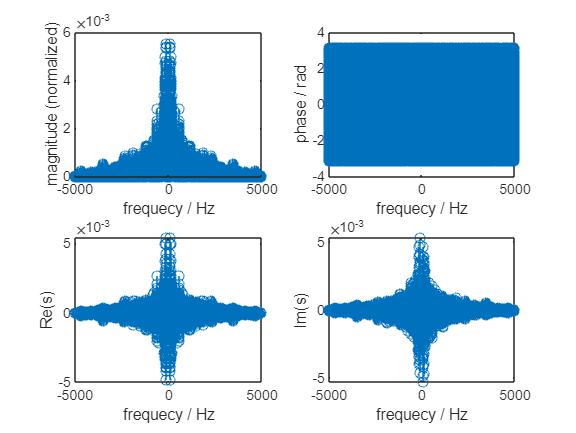


% Generate signal
type = structure.signal_type; % Signal type
fs = structure.fs; % Signal sampling frequency
duration = structure.signal_duration_s; % Duration of signal
T = structure.periodicity_s; % Period IS THIS NECESSARY?? Fundamental freq?
frequencies = structure.frequencies; % Frequencies in the signal
t = 0:1/fs:duration-1/fs; % Time vector
signal = zeros(1,length(t)); % Initialize signal with zeros
if strcmp(type, 'tone') % Check if signal type is a tone
    for i = 1:length(frequencies)
        signal = signal+cos(2*pi*frequencies(i)*t); %Construct the signal
    end
end
% DFT
% Make spectrum takes in the signal and its fs, and gives NORMALIZED
% spectrum and a frequency vector. Also plots.
[Y_wav, f_wav] = make_spectrum(y, fs_y);

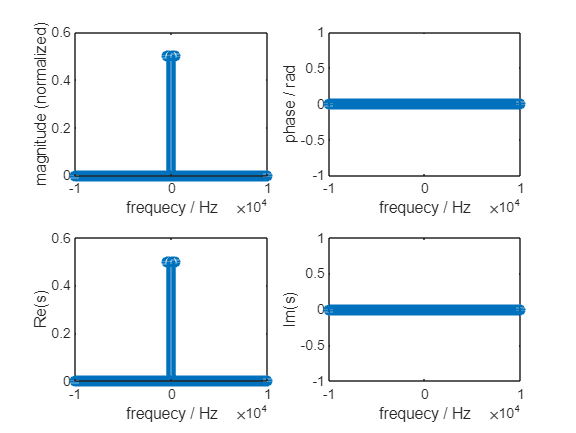

[Y_signal,f_signal] = make_spectrum(signal,fs);

% Plotting 

x_lim = structure.x_lim_time

x_lim = 0.0100

y_lim = structure.y_lim_amplitude

y_lim = 1

x_axis_type = structure.x_axis_type

x_axis_type = 'lin'

y_axis_type = structure.y_axis_type

y_axis_type = 'log'

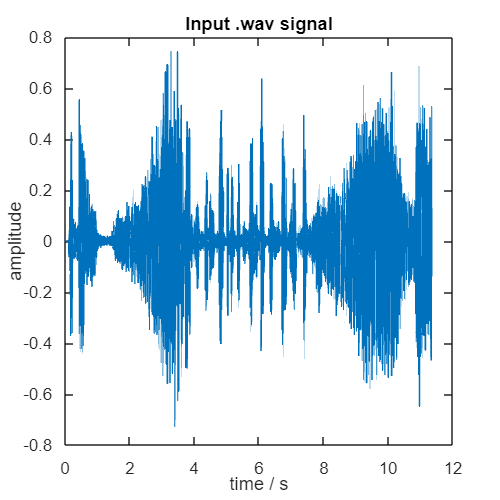

x_lim_frequency = structure.x_lim_frequency;
y_lim_au = structure.y_lim_au;
% Time signals
figure('Name','.wav time signal','Position',[400 300 400 400])
% define papersize for export
set(gcf,'paperunits','centimeters','Paperposition',[0 0 10 4])
h1 = plot(t_y,y);
set(h1, 'linewidth',1)
set(gca,'Fontsize',10)
title('Input .wav signal')
% ylim([0,y_lim])
% xlim([0,x_lim])
xlabel('time / s')
ylabel('amplitude')

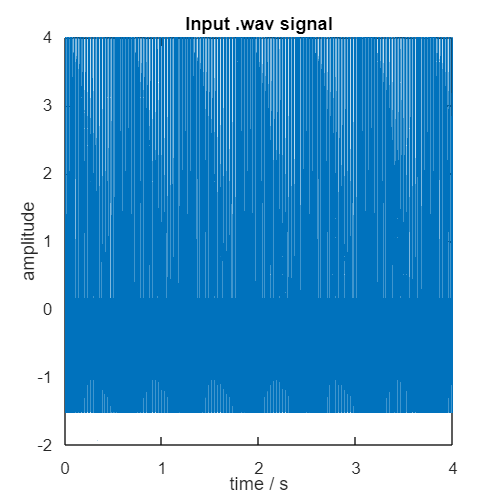


%Synthesized signal
figure('Name','.wav time signal','Position',[400 300 400 400])
set(gcf,'paperunits','centimeters','Paperposition',[0 0 10 4])
h2 = plot(t,signal);
set(h2, 'linewidth',1)
set(gca,'Fontsize',10)
title('Input .wav signal')
% ylim([0,y_lim])
% xlim([0,x_lim])
xlabel('time / s')
ylabel('amplitude')



% Magnitude/phase

% Real/imaginary parts

% Pole/zero diagram

%Filter transfer function